# Position Plotter

Daniel Dymond 2021

Plots the position of the ABB-2600-12/1.85 Robot

## User Parameters

% Theta Position for Frames 1 - 7
theta = [0 0 0 0 0 0 0];

## Computation Script

Obtain Robot Frames and DH data using setupRobot method

syms s1 c1 s2 c2 s3 c3 s4 c4 s5 c5 s6 c6 s7 c7
syms t1 t2 t3 t4 t5 t6 t7
theta_syms = [t1 t2 t3 t4 t5 t6 t7];
trig_syms = [s1 c1 s2 c2 s3 c3 s4 c4 s5 c5 s6 c6 s7 c7];
[T_brk, T_sub] = setupRobot();

Generate numerical values for T matrices

T_10 = subs(cell2sym(T_brk(1)), theta_syms, theta);
T_20 = subs(cell2sym(T_brk(2)), theta_syms, theta);
T_30 = subs(cell2sym(T_brk(3)), theta_syms, theta);
T_40 = subs(cell2sym(T_brk(4)), theta_syms, theta);
T_50 = subs(cell2sym(T_brk(5)), theta_syms, theta);
T_60 = subs(cell2sym(T_brk(6)), theta_syms, theta);
T_70 = subs(cell2sym(T_brk(7)), theta_syms, theta);

Create Plot

outputPlot = plot(1);
view(3);
hold on;

Show the Path Preview

outputPlot = drawDesiredPath();

Draw Each link and axis

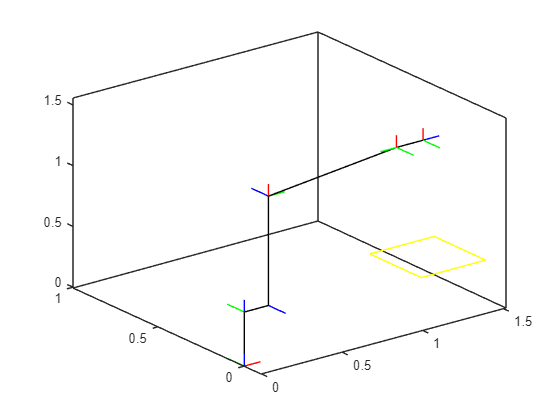

F_0 = eye(4);
outputPlot = drawAxis(F_0);

F_1 = F_0 * T_10;
outputPlot = plot3([F_0(1,4) T_10(1,4)], [F_0(2,4) T_10(2,4)], [F_0(3,4) T_10(3,4)], 'black');
outputPlot = drawAxis(F_1);

F_2 = F_0  * T_20;
outputPlot = drawAxis(F_2);
outputPlot = plot3([T_10(1,4) T_20(1,4)], [T_10(2,4) T_20(2,4)], [T_10(3,4) T_20(3,4)], 'black');

F_3 = F_0  * T_30;
outputPlot = drawAxis(F_3);
outputPlot = plot3([T_20(1,4) T_30(1,4)], [T_20(2,4) T_30(2,4)], [T_20(3,4) T_30(3,4)], 'black');


F_4 = F_0  * T_40;
outputPlot = drawAxis(F_4);
outputPlot = plot3([T_30(1,4) T_40(1,4)], [T_30(2,4) T_40(2,4)], [T_30(3,4) T_40(3,4)], 'black');


F_5 = F_0  * T_50;
outputPlot = drawAxis(F_5);
outputPlot = plot3([T_40(1,4) T_50(1,4)], [T_40(2,4) T_50(2,4)], [T_40(3,4) T_50(3,4)], 'black');


F_6 = F_0  * T_60;
outputPlot = drawAxis(F_6);
outputPlot = plot3([T_50(1,4) T_60(1,4)], [T_50(2,4) T_60(2,4)], [T_50(3,4) T_60(3,4)], 'black');

F_7 = F_0  * T_70;
outputPlot = drawAxis(F_7);
outputPlot = plot3([T_60(1,4) T_70(1,4)], [T_60(2,4) T_70(2,4)], [T_60(3,4) T_70(3,4)], 'black');